## Project 1

### Sentences for pro 1: ‘C_01_01.wav’ & ‘C_01_02.wav’ 

### Task 1 

#### • Set LPF cut-off frequency to 50 Hz. 将低通滤波截止频率设置为50Hz。

#### • Implement tone-vocoder by changing the number of bands to N=1, N=2, N=4, N=6, and N=8.

#### • Save the wave files for these conditions, and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

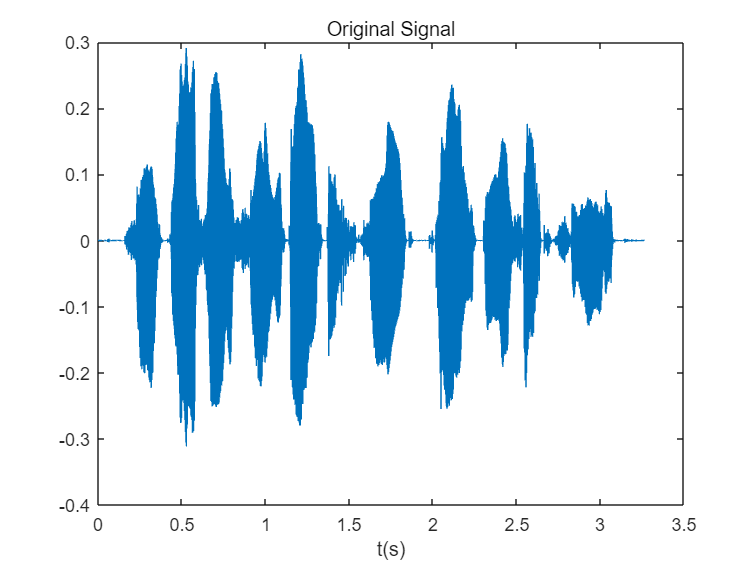

[x1,~]=audioread("C:\Users\Lenovo\Desktop\Signals and system\Project1\C_01_01.wav");
[x2,fs]=audioread("C:\Users\Lenovo\Desktop\Signals and system\Project1\C_01_02.wav");

fcut=50;

figure
plot(xTime(x1,fs),x1),title('Original Signal'),xlabel('t(s)')

SSN=createSSN(x1,fs);

Frequency-to-place mapping in cochlea:


$$f=165\ldotp 4\times \left({10}^{0\ldotp 06\cdot d} -1\right)$$


where $f$ is -3 dB cut-off frequency, and $d$ is the distance (in millimeter) along the cochlea.

**Task1**

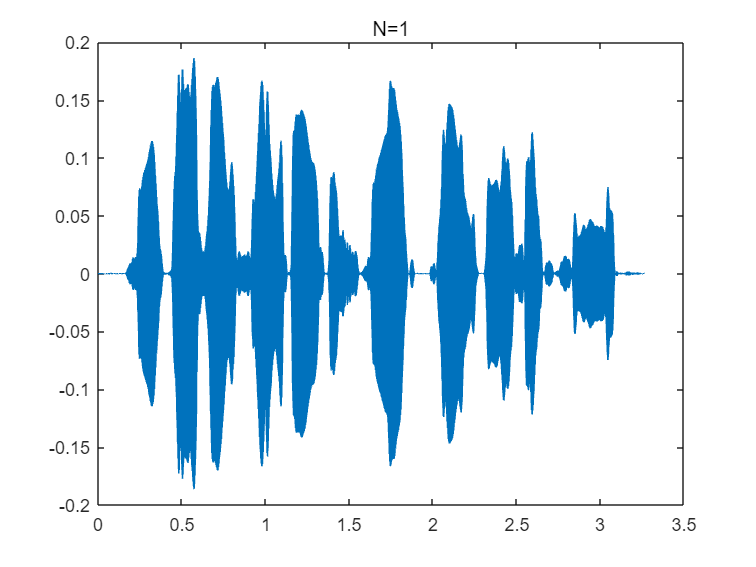

n1=4,n2=4%具体优化值有待讨论？？？？？？？？？？？？？？？？？？

%set the cut-off frequency to 50Hz
y1=Synthesize(x1,1,n1,n2,50,fs);
y2=Synthesize(x1,2,n1,n2,50,fs);
y4_with_SSN=Synthesize(x1,4,n1,n2,50,fs);
y6_with_SSN=Synthesize(x1,6,n1,n2,50,fs);
y8_with_SSN=Synthesize(x1,8,n1,n2,50,fs);

figure
plot(xTime(y1,fs),y1),title('N=1')

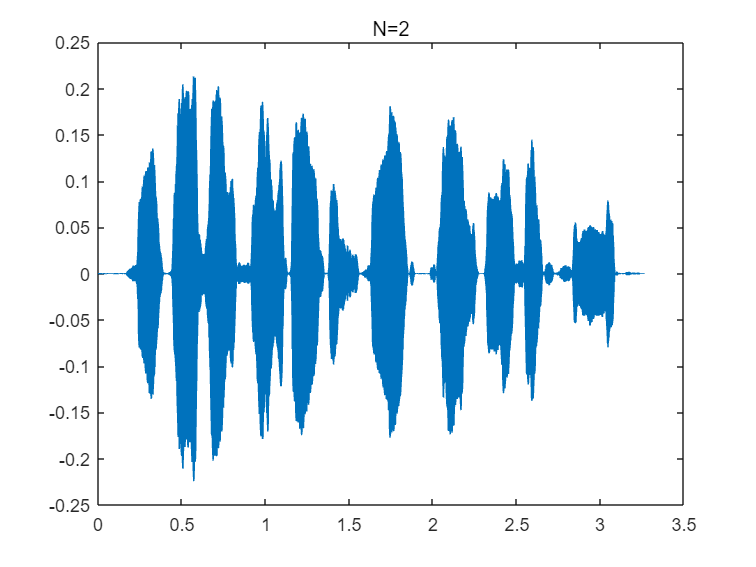

plot(xTime(y2,fs),y2),title('N=2')

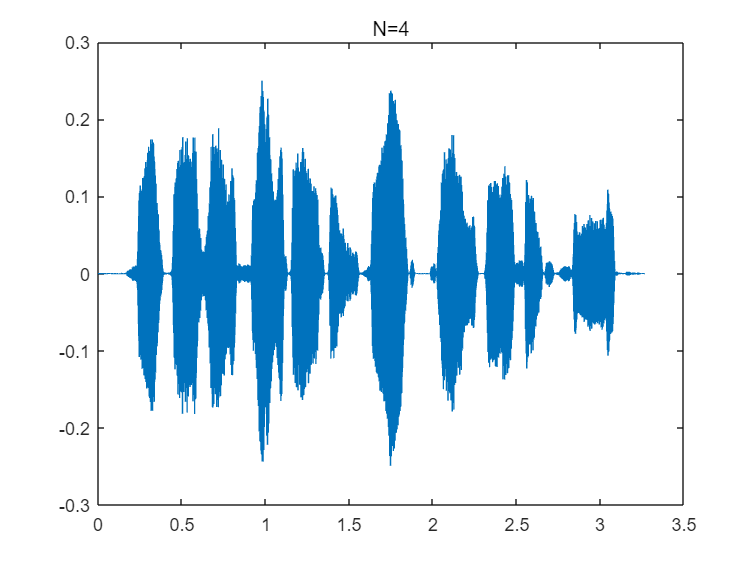

plot(xTime(y4_with_SSN,fs),y4_with_SSN),title('N=4')

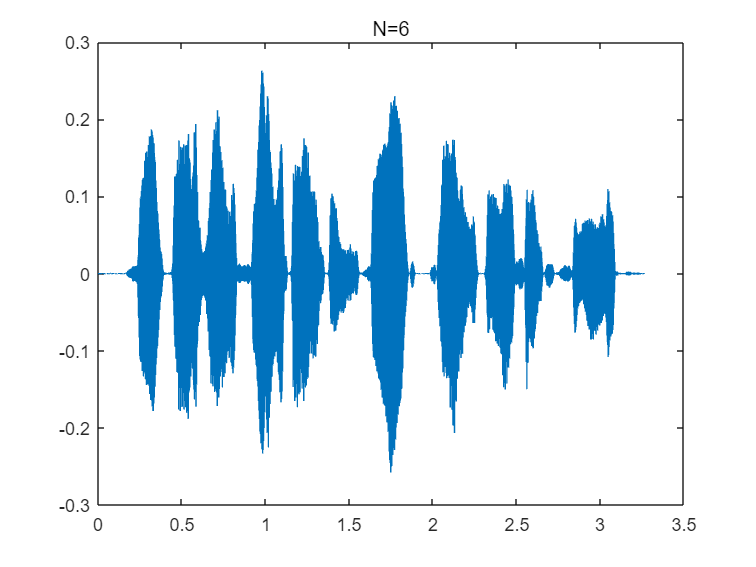

plot(xTime(y6_with_SSN,fs),y6_with_SSN),title('N=6')

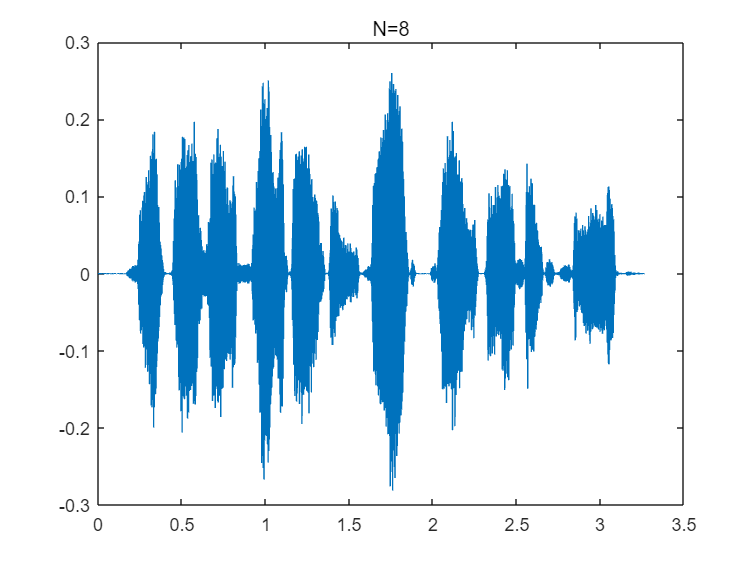

plot(xTime(y8_with_SSN,fs),y8_with_SSN),title('N=8')

**Task2**

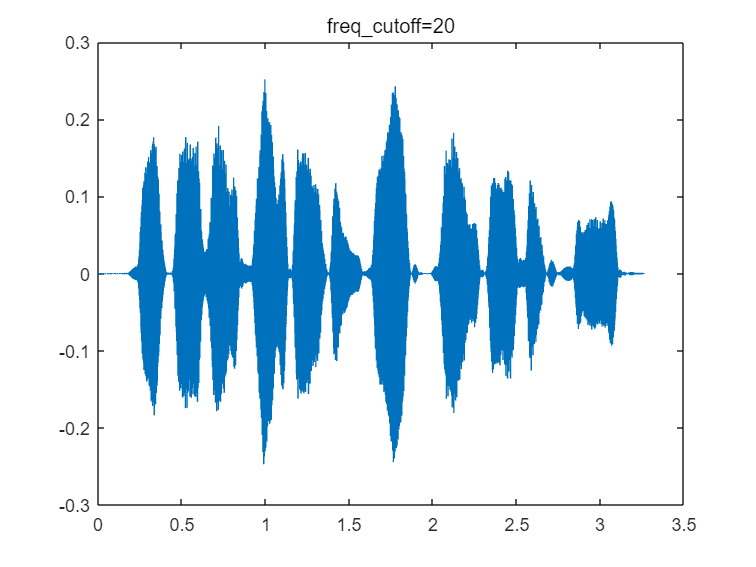

%set the number of bands to N=4
y_fs_20=Synthesize(x1,4,n1,n2,20,fs);
y_fs_50=Synthesize(x1,4,n1,n2,50,fs);
y_fs_100=Synthesize(x1,4,n1,n2,100,fs);
y_fs_400=Synthesize(x1,4,n1,n2,400,fs);

figure
plot(xTime(y_fs_20,fs),y_fs_20),title('freq\_cutoff=20')

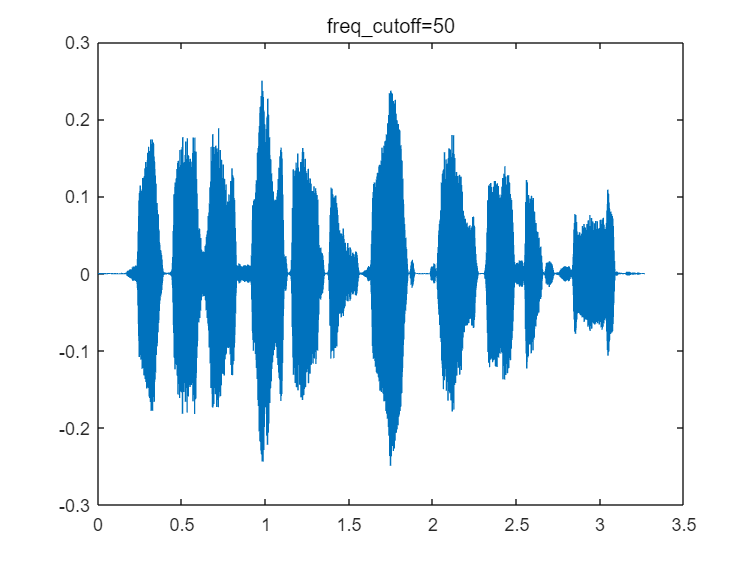

plot(xTime(y_fs_50,fs),y_fs_50),title('freq\_cutoff=50')

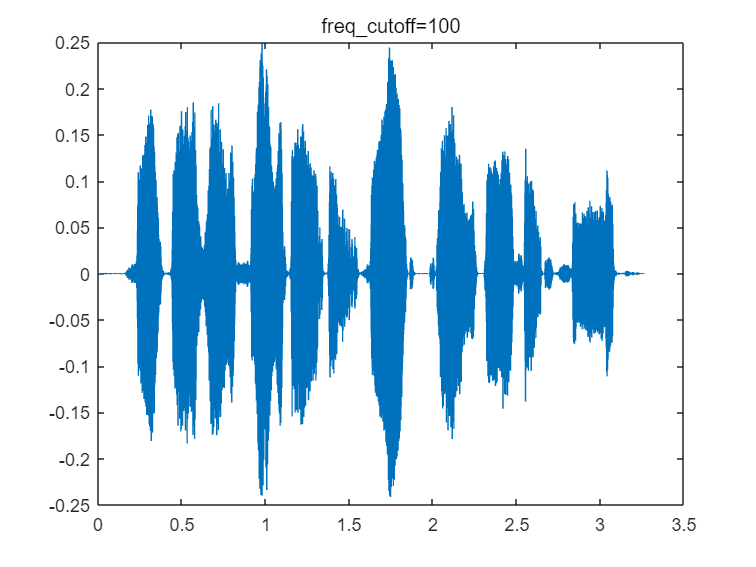

plot(xTime(y_fs_100,fs),y_fs_100),title('freq\_cutoff=100')

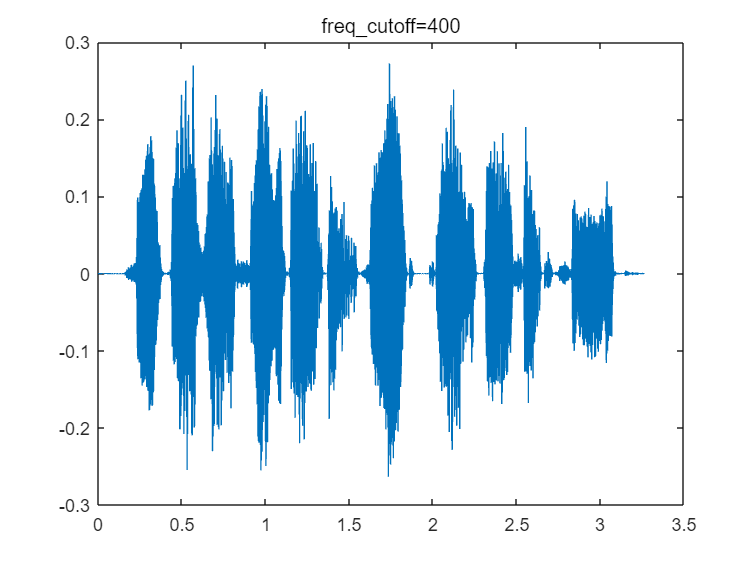

plot(xTime(y_fs_400,fs),y_fs_400),title('freq\_cutoff=400')

**Task3**

SNR=-5

SSN=SSN/norm(SSN)*norm(x1)*10^0.25;

SSN =    -0.1467   -0.1150   -0.0993   -0.0783    0.0310    0.1093    0.1281    0.1811    0.1861    0.1697    0.1231    0.0649   -0.0023   -0.0340   -0.0254    0.0592    0.0751    0.0972    0.0964    0.0847    0.0569   -0.0313   -0.0773   -0.0675   -0.0362   -0.0588   -0.0158    0.0657    0.0697    0.1042    0.0847    0.0097    0.0303   -0.0034   -0.0734   -0.0645   -0.0670   -0.0392   -0.0091    0.0174   -0.0297   -0.0200   -0.0412   -0.0756   -0.0837   -0.1289   -0.0992   -0.0453    0.0031    0.0550


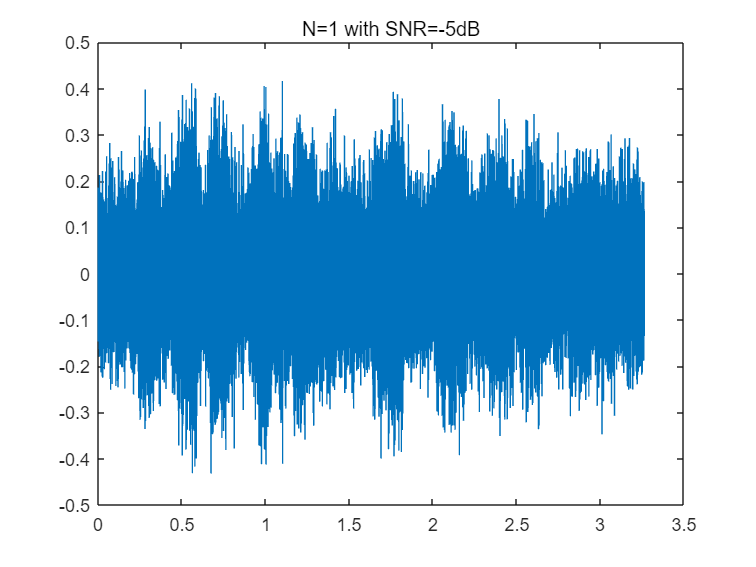


%set the cut-off frequency to 50Hz
y1_with_SSN=Synthesize(x1,1,n1,n2,50,fs)+SSN;
y2_with_SSN=Synthesize(x1,2,n1,n2,50,fs)+SSN;
y4_with_SSN=Synthesize(x1,4,n1,n2,50,fs)+SSN;
y6_with_SSN=Synthesize(x1,6,n1,n2,50,fs)+SSN;
y8_with_SSN=Synthesize(x1,8,n1,n2,50,fs)+SSN;

figure
plot(xTime(y1_with_SSN,fs),y1_with_SSN),title('N=1 with SNR=-5dB')

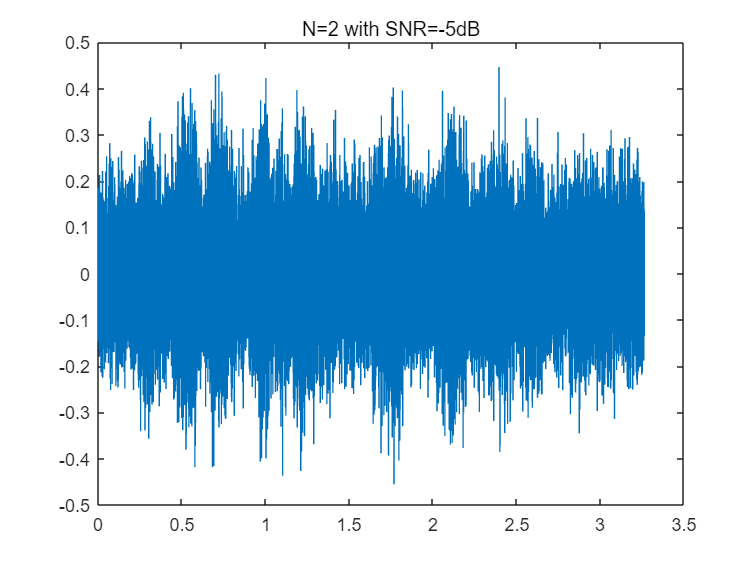

plot(xTime(y2_with_SSN,fs),y2_with_SSN),title('N=2 with SNR=-5dB')

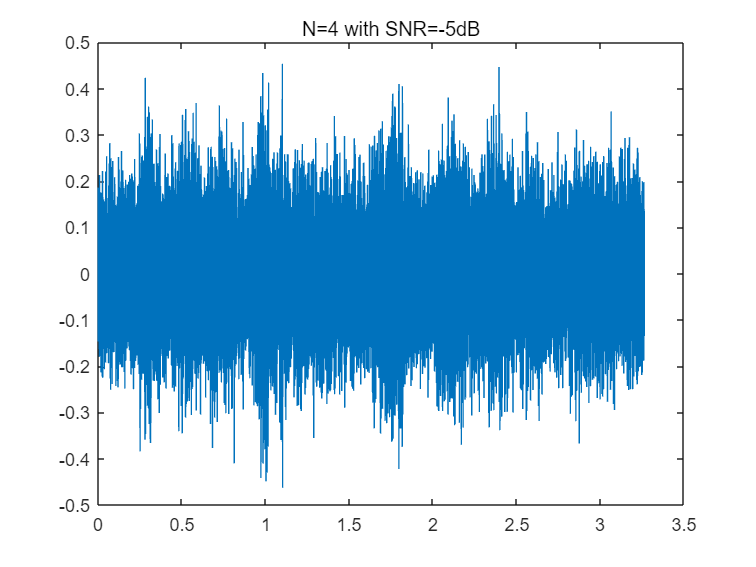

plot(xTime(y4_with_SSN,fs),y4_with_SSN),title('N=4 with SNR=-5dB')

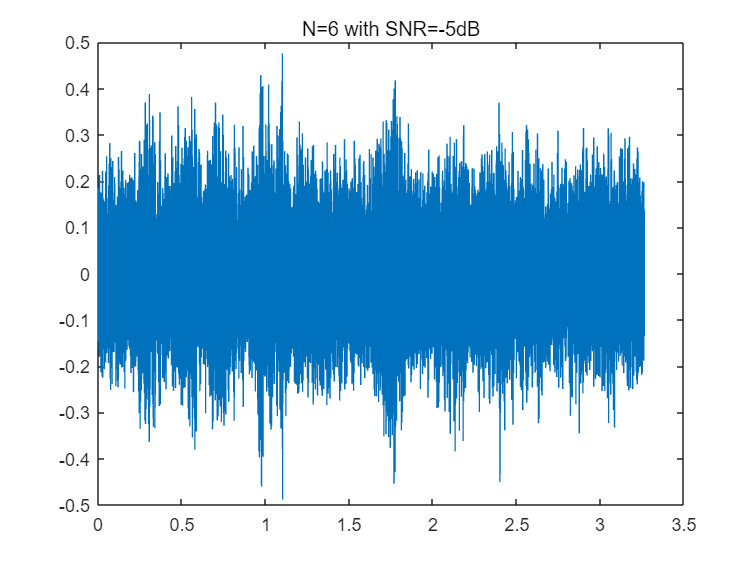

plot(xTime(y6_with_SSN,fs),y6_with_SSN),title('N=6 with SNR=-5dB')

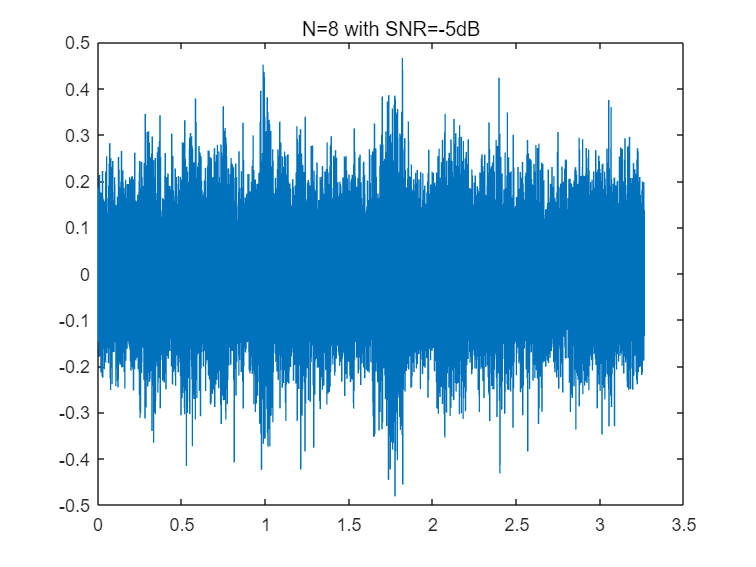

plot(xTime(y8_with_SSN,fs),y8_with_SSN),title('N=8 with SNR=-5dB')

**Task4**

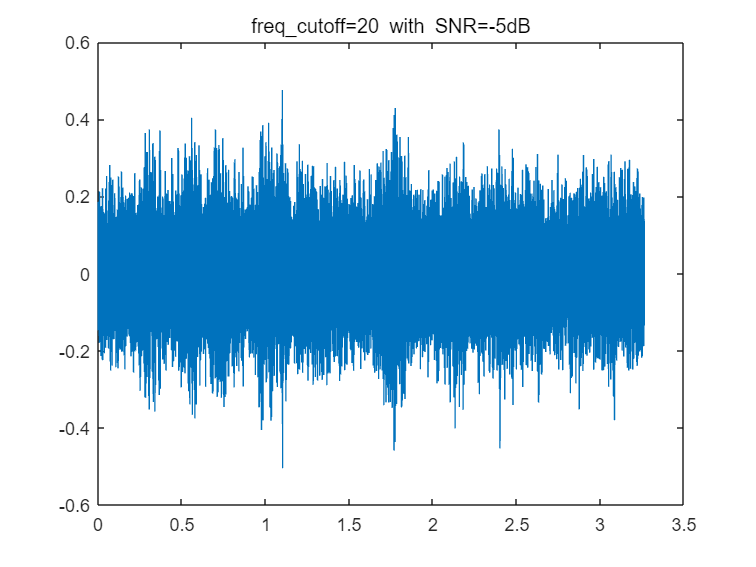

%set the number of bands to N=6
y_fs_20_with_SSN=Synthesize(x1,6,n1,n2,20,fs)+SSN;
y_fs_50_with_SSN=Synthesize(x1,6,n1,n2,50,fs)+SSN;
y_fs_100_with_SSN=Synthesize(x1,6,n1,n2,100,fs)+SSN;
y_fs_400_with_SSN=Synthesize(x1,6,n1,n2,400,fs)+SSN;

figure
plot(xTime(y_fs_20_with_SSN,fs),y_fs_20_with_SSN),title('freq\_cutoff=20 with SNR=-5dB')

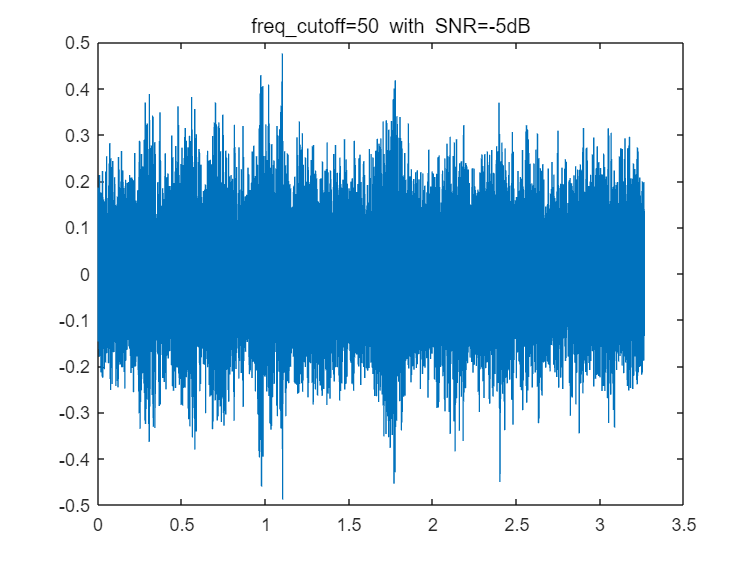

plot(xTime(y_fs_50_with_SSN,fs),y_fs_50_with_SSN),title('freq\_cutoff=50 with SNR=-5dB')

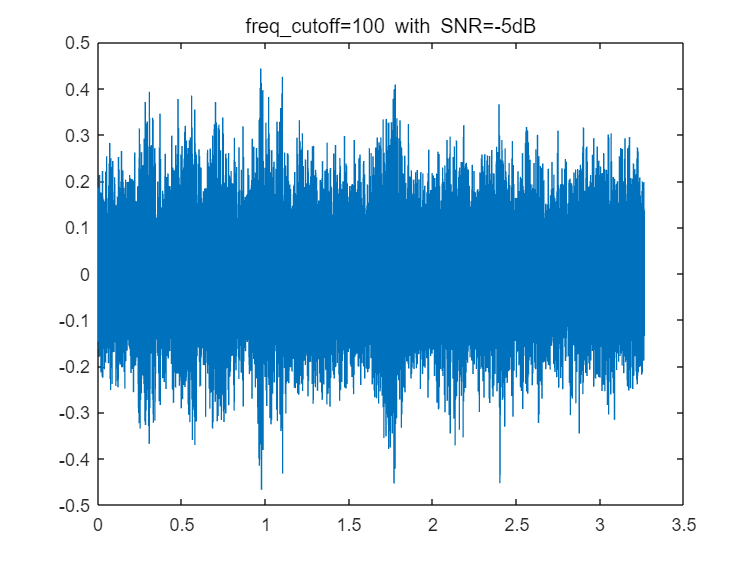

plot(xTime(y_fs_100_with_SSN,fs),y_fs_100_with_SSN),title('freq\_cutoff=100 with SNR=-5dB')

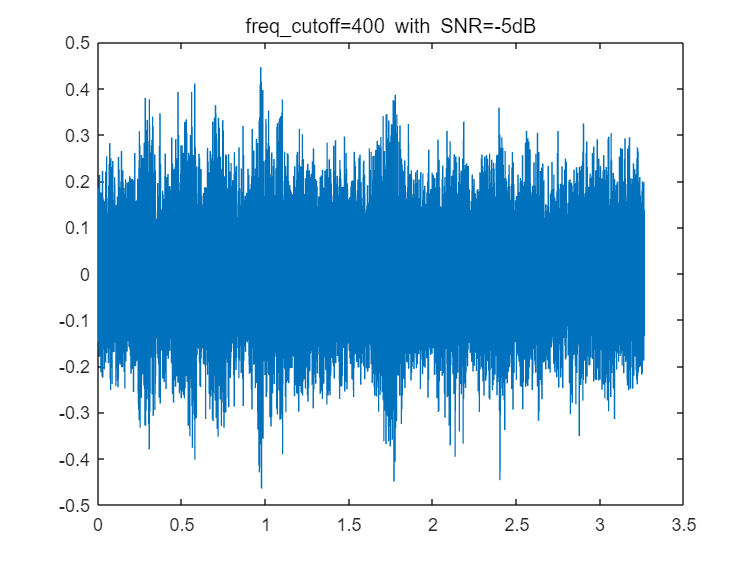

plot(xTime(y_fs_400_with_SSN,fs),y_fs_400_with_SSN),title('freq\_cutoff=400 with SNR=-5dB')

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function SSN=createSSN(x,fs)%上节课做的生成SSN
    x=x';
    sig=repmat(x,1,10);
    nfft=512;
    [Pxx,w]=pwelch(sig,hamming(nfft),nfft/2,nfft,fs);
    b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
    white_noise=1-2*rand(1,length(x)+3000);
    SSN=filter(b,1,white_noise);
    SSN=SSN(2000:end);
    %Discard the beginning which has little sound.
    SSN=SSN(1:length(x));
end

function Fs=createBandDivision(N)

    %输入想要获得多少个带
    %Fs是每个带的频率区间，每个元素都是二元素向量
    fmin=200;
    fmax=7000;
    dmin=log10(fmin/165.4+1)/0.06;
    dmax=log10(fmax/165.4+1)/0.06;
    D=linspace(dmin,dmax,N+1);
    F=zeros(1,N+1);
    for k=1:N+1
        F(k)=165.4*(10^(0.06*D(k))-1);
    end
    Fs=zeros(N,2);
    for k=1:N
        Fs(k,:)=[F(k),F(k+1)];
    end
end

function y=Synthesize(x,N,n1,n2,fcut,fs)
    %输入音频x，切割带数N，n1带通滤波阶数，n2低通滤波阶数
    Fs=createBandDivision(N);
    y=zeros(1,length(x));

    for k=1:N
        [b1,a1]=butter(n1,Fs(k,:)/(fs/2),"bandpass");
        y_filtered=filter(b1,a1,x);

        [b2,a2]=butter(n2,fcut/(fs/2),'low');
        %取包络选择什么滤波器？？？？？？？？？？？？？？？？？？？阶数？？？？？？？？？？？？？？？？？？？？？？
        y_env=filter(b2,a2,abs(y_filtered));

        sine_wave_freq=(Fs(k,1)+Fs(k,2))/2;
        sine_wave=sin(2*pi*sine_wave_freq*xTime(y_env,fs));

        y_modulation=y_env'.*sine_wave;

        y=y+y_modulation;
        y=y./norm(y).*norm(x);
    end
end